clearvars; close all; clc

% 频段
f_low=2;f_high=15;
% 时间位移最大量
T=10;

% 导入数据
statenum = "state1";
subclass = "child";% adult or child
chan_index = 'fp';

fn_load_actual = strcat("tf_results_",chan_index,"/tf_",subclass,"_",statenum,".mat");
fn_load_phaseran = strcat("tf_results_",chan_index,"/tf_phaseran_",subclass,"_",statenum,".mat");
load(fn_load_actual);
load(fn_load_phaseran);
% if subclass == "adult"
%     if statenum == "state1"
%         load('tf_results\tf_phaseran_adult_state1.mat');
%         load('tf_results\tf_adult_state1.mat');
%     elseif statenum == "state2"
%         load('tf_results\tf_phaseran_adult_state2.mat');
%         load('tf_results\tf_adult_state2.mat');
%     end
% end
% if subclass == "child"
%     if statenum == "state1"
%         load('tf_results\tf_phaseran_child_state1.mat');
%         load('tf_results\tf_child_state1.mat');
%     elseif statenum == "state2"
%         load('tf_results\tf_phaseran_child_state2.mat');
%         load('tf_results\tf_child_state2.mat');
%     end
% end

sperm_phaseran_mu = mean(sperm_phaseran_all_mean,3);
musigma_hat = zeros([f_high-f_low+1,2*T+1,2]);
p_phaseran = zeros(size(sperm_phaseran_all_mean));
p_actual = zeros(size(sperm_all_mean));
Z_phaseran = zeros(size(sperm_phaseran_all_mean));
Z_actual = zeros(size(sperm_all_mean));

% 遍历频率和时间位移
for f=1:size(sperm_phaseran_all_mean,1)
    for t=1:size(sperm_phaseran_all_mean,2)
        % 导入随机数据序列和实际数据
        x_phaseran = reshape(sperm_phaseran_all_mean(f,t,:),[1000,1]);
        x_actual = sperm_all_mean(f,t);
        % 计算均值、标准差
        musigma_hat(f,t,:) = mle(x_phaseran);
        mshat = mle(x_phaseran);
        % 计算分位数作为p_value
        p_phaseran(f,t,:) = normcdf(x_phaseran,mshat(1),mshat(2));
        p_actual(f,t) = normcdf(x_actual,mshat(1),mshat(2));
        %计算Z值
        Z_phaseran(f,t,:) = (x_phaseran-mshat(1))/mshat(2);                
        Z_actual(f,t) = (x_actual-mshat(1))/mshat(2);        
    end
end

% 矩阵二值化：p<0.05设置为1
ind=(p_actual<0.05|p_actual>0.95);
p_actual(ind)=1;
p_actual(~ind)=0;
% 矩阵二值化：p<0.05设置为1
ind=(p_phaseran<0.05|p_phaseran>0.95);
p_phaseran(ind)=1;
p_phaseran(~ind)=0;

CC_actual = bwconncomp(p_actual);
Clu_size_actual = zeros([length(CC_actual.PixelIdxList),1]);
%% 方法1
% 统计最大Cluster所包含的Pixel的个数
for i=1:length(CC_actual.PixelIdxList)
    Clu_size_actual(i) = length(cell2mat(CC_actual.PixelIdxList(i)));
end
% Clu_size_max_actual = max(Clu_size_actual);

Clu_size_max_ran = zeros([1000,1]);
for i=1:1000
    CC_phaseran = bwconncomp(p_phaseran(:,:,i));
    % 统计最大Cluster所包含的Pixel的个数
    len = length(CC_phaseran.PixelIdxList);
    
    if len>0
        Clu_size_ran = zeros([length(CC_phaseran.PixelIdxList),1]);
        for l=1:length(CC_phaseran.PixelIdxList)
            Clu_size_ran(l) = length(cell2mat(CC_phaseran.PixelIdxList(l)));
        end
        Clu_size_max_ran(i) = max(Clu_size_ran);
    end   
end

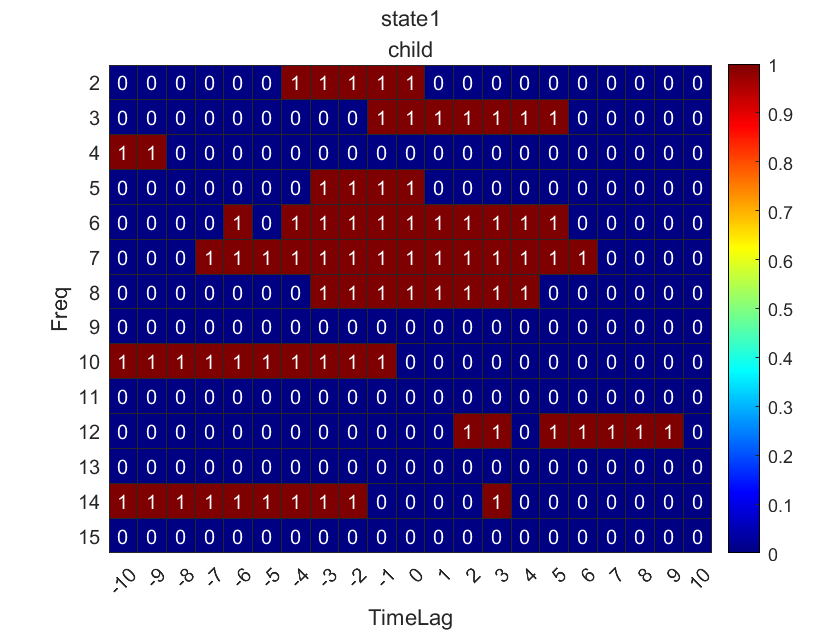

p_mask_size=zeros([length(Clu_size_actual),1]);
mshat_mask = mle(Clu_size_max_ran);
for i=1:length(Clu_size_actual)
    p_mask_size(i) = normcdf(Clu_size_actual(i),mshat_mask(1),mshat_mask(2));
end
h = draw_heatmap(p_actual,T,f_low,f_high,[statenum,subclass],0,1);

Z_actual_v = reshape(Z_actual,[size(p_actual,1)*size(p_actual,2),1]);
Clu_sum_actual = zeros([length(CC_actual.PixelIdxList),1]);
%% 方法2
% 统计最大Cluster所包含的Pixel的个数
for i=1:length(CC_actual.PixelIdxList)
    Clu_sum_actual(i) = sum(Z_actual_v(cell2mat(CC_actual.PixelIdxList(i))));
    %Clu_sum_actual(i) = sum(abs(Z_actual_v(cell2mat(CC_actual.PixelIdxList(i)))));
end

Clu_sum_max_ran = zeros([1000,1]);
for i=1:1000
    CC_phaseran = bwconncomp(p_phaseran(:,:,i));
    Z_phaseran_v = reshape(Z_phaseran(:,:,i),[size(p_phaseran,1)*size(p_phaseran,2),1]);
    % 统计最大Cluster所包含的Pixel的个数
    len = length(CC_phaseran.PixelIdxList);
    
    if len>0
        Clu_sum_ran = zeros([length(CC_phaseran.PixelIdxList),1]);
        for l=1:length(CC_phaseran.PixelIdxList)
            Clu_sum_ran(l) = sum(Z_phaseran_v(cell2mat(CC_phaseran.PixelIdxList(l))));
            %Clu_sum_ran(l) = sum(abs(Z_phaseran_v(cell2mat(CC_phaseran.PixelIdxList(l)))));
        end
        % 取绝对值最大的数
        [~,loc]=max(abs(Clu_sum_ran));
        Clu_sum_max_ran(i) = Clu_sum_ran(loc);
    end   
end

p_mask_sum=zeros([length(Clu_sum_actual),1]);
mshat_mask = mle(Clu_sum_max_ran);
for i=1:length(Clu_sum_actual)
    p_mask_sum(i) = normcdf(Clu_sum_actual(i),mshat_mask(1),mshat_mask(2));
end

% 保存文件
% fn_sav = strcat("tf_results/tf_",subclass,"_",statenum,".mat");
% save(fn_sav,"sperm_all")